# Asteroid Optical Navigation

ASEN 5044 Final Project Description

*Group Members: *James Monaco, AJ Cuddeback, Grant Kirchoff

## Part 1: Deterministic System Analysis

### 1. Nonlinear Simulation

run('sim_setup.m')
load orbitdetermination-finalproj_data_2023_11_14.mat



% solar radiation pressure 
a_SRP = -Phi_0 / norm(r_S)^2 * (1 + 4/9 * rho) * A_M * r_S / norm(r_S);

% non-linear simualtion
x_0 = [r_0_nom; dr_0_nom];
options = odeset('RelTol',1e-12);
t_obs = unique(y_table(:, 1));  % [s]
[t_ode45,x_ode45] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t_obs, x_0, options);

% plotting non-linear simulation solution
figure(1);
fig = tiledlayout(6,1)

fig =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [6 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


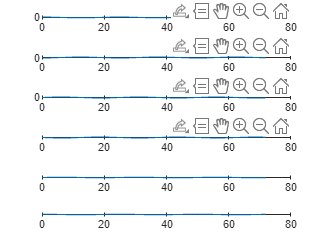

for i = 1:6
    nexttile(fig)
    plot(t_ode45/60/60,x_ode45(:,i))
end

### **2. Measurement Model**

Start with "fake" landmark at the center of the asteroid for a sanity check i.e., $l={\left\lbrack 0,0,0\right\rbrack }^T$

r = x_ode45(:, 1:3)';

t_obs = unique(y_table(:, 1));
steps = length(t_obs);

% start with centered landmark (l=0)
% l = [0, 0, 0]';
l = pos_lmks_A(:,10);

utot = zeros(1, steps);
vtot = zeros(1, steps);
for jj=1:steps
    RNC = R_CtoN(:, :, jj);
    % w_A is stupid, and is a peridicity [sec/rot]
    % 1/period * sec is number of rotations
    % rotations * 2 * pi is radians 
    th = 2* pi * 1/w_A * t_obs(jj);  % [deg]
    R_NA = [cos(th) -sin(th) 0; 
            sin(th) cos(th)  0; 
            0       0        1];
    [u, v] = measure(l, r(:, jj), RNC, u_0, v_0, f, R_NA);
    utot(1, jj) = u;
    vtot(1, jj) = v;
end

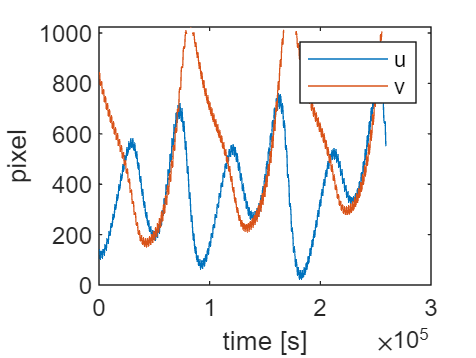

figure
plot(t_obs, utot)
hold on
plot(t_obs, vtot)
legend('u', 'v')
xlabel('time [s]')
ylabel('pixel')

### 2. CT Jacobians

Solved by hand

### 3. DT Linarized Model

No code for this? Maybe put DT LTI matrices here?

### 4. Simlation of DT linearized Model

No process noise, no measurement nose, no control input perturbations. Simulation goes here:

Validating against full nonlinear simulation: 

Plotting results: 

## Part 2: Stochastic Nonlienar Filtering

### 5. Linarized KF 

- Use specified nominal state trajectory, control inputs, and covariance matrix

-  Use NEES and NIS $\chi^2
$ test based on MC TMT simulations to tune and validate LKF

### 6. Extended KF 

### 7. Implement LKF and EKF for Estimation

function dx = orbit(~,x_in,a_SRP,mu_A)
    % calculating pertibation forces
    r = x_in(1:3);
    f = a_SRP + a_2B(r,mu_A);
    
    % building the derivative vector
    dx = zeros(size(x_in));
    dx(1:3) = x_in(4:6);
    dx(4:6) = f;
end

function f = a_2B(r,mu_A)
    f = -mu_A / norm(r)^3 * r;
end 

function [u, v] = measure(l, r, RNC, u0, v0, f, R_NA)
    % calculate pixel coordinate of SC
    
    % unit vectors of camera
    ihat = RNC(:, 1);
    jhat = RNC(:, 2);
    khat = RNC(:, 3);

    % transformed coords based on asteriod rotation
    % the coords of the satellite are in the inertial frame, and do NOT
    % require transformation 
    l = R_NA * l;

    u = f * ((l-r)'*ihat)/((l-r)'*khat) + u0;
    v = f * ((l-r)'*jhat)/((l-r)'*khat) + v0;

    if u<0 || u>1024 
        u = NaN;
    end
    if v<0 || v>1024
        v = NaN;
    end
    if (l-r)'*khat < 0
        u = NaN;
        v = NaN;
    end

end